SUBJECT='DM1033';
SESSION='intraop';


PATH_DATASET = 'Y:\DBS';
% PATH_DATASET = '/Volumes/Nexus4/DBS';

PATH_DER = [PATH_DATASET filesep 'derivatives'];
PATH_DER_SUB = [PATH_DER filesep 'sub-' SUBJECT];  
PATH_PREPROC = [PATH_DER_SUB filesep 'preproc'];
PATH_ANNOT = [PATH_DER_SUB filesep 'annot'];

PATH_LEADDBS = [PATH_DER_SUB filesep 'Herrington_leaddbs_refined']; 

PATH_CORTEX = [PATH_DATA '/derivatives/' SUBJECT '/freesurfer/freesurfer'];
PATH_LOC = [PATH_DATA '/derivatives/' SUBJECT '/freesurfer/freesurfer/Electrode_Locations'];
PATH_FREESURFER = [PATH_DATA '/derivatives/' SUBJECT '/freesurfer/freesurfer'];
PATH_MNI_BRAIN = 'E:/MATLAB/lead_v2.3/templates/space/MNI_ICBM_2009b_NLIN_ASYM/cortex/CortexHiRes.mat';

cd(PATH_PREPROC)


Load cortical surface

which lead_dbs

^Ensure this says LeadDBS_Classic. This step has only been verified with the 'classic' (<v2.6, non-bids) version of lead-dbs. If it does not, remove the current Lead-DBS from your path and add a classic version. 

Open the lead_dbs gui. 

- Click 'choose patient directory' and navigate to the leaddbs_coreg_preopct2preopmri folder created above. 

- Check the 'coregister volumes' box and click 'Run'. 

lead_dbs

C:\Program Files\LeadDBS_Classic\leaddbs\lead_dbs.m


Check that lead_dbs successfully co-registered the pre-op ct with your favorite imaging software (ITK-SNAP, slicer, etc)

Copy the registered preop/intraop CT (unfortunately called 'rpostop_ct.nii') into the ecogloc folder.  

                 Welcome to                            
                                                            
  _______________________________________                   
 /           ______     ___      _____   \                  
 | | ocali-  |         /   \    |     \  |             _______   
 | | zation  | lec     |   |    | BS   \ |          = / O   / \  
 | |         |---      /___\    | Sur- | |         = (   \./___) 
 | | of      | trodes |     |   | gery / |        =   \_ __ _)   
 | |_____    |_____   / fter \  |_____/  |         =   (O)(O)    
 \_______________________________________/                  
                                                            
                   Toolbox.                            
                     v2.6                    


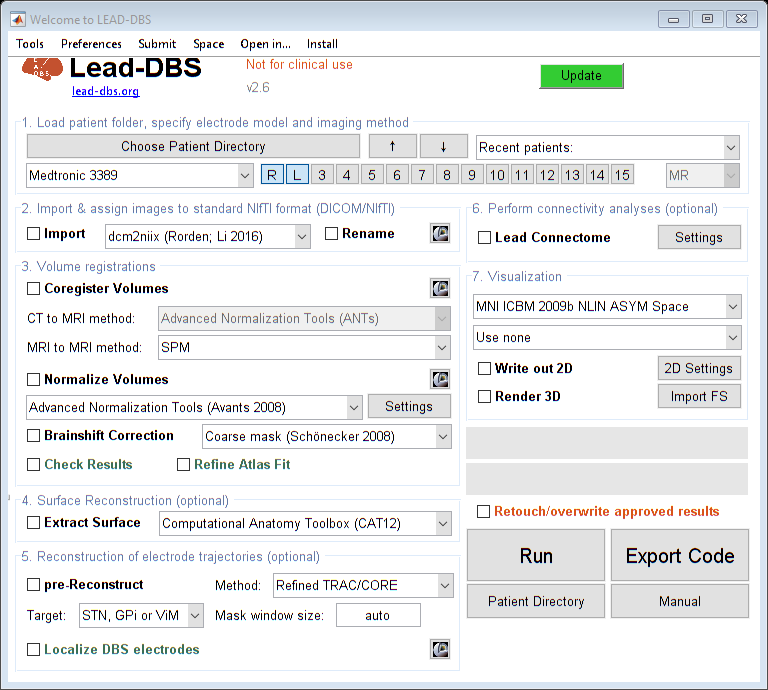

copyfile([PATH_LEADDBS filesep 'anat_t1.nii'], [PATH_ECOGLOC filesep 'preop_mri.nii']); 

copyfile([PATH_LEADDBS filesep 'rpostop_ct.nii'], [PATH_ECOGLOC filesep 'rpostop_ct.nii']);
copyfile([path_preopct_coreg filesep 'rpostop_ct.nii'], [PATH_ECOGLOC filesep 'rpreop_ct.nii']);